clc; clear; close all;
results = struct();
num = struct();
for i = 1:20
    filename =  ['E:\医学大数据\homework9\face\face\' num2str(i) ];    
    [result,num_images] = pre_process(filename);    
    results.(sprintf('result%d', i)) = result;
    num.(sprintf('num%d',i)) = num_images;
end

weights = struct();
mean_faces = struct();
% Principal_components = struct();
Eigenvectors = struct();
fieldNames1 = fieldnames(results);
fieldNames2 = fieldnames(num);
for i = 1:numel(fieldNames1)
    fieldName1 = fieldNames1{i};
    fieldName2 = fieldNames2{i};
    currentData = results.(fieldName1);
    numData = num.(fieldName2);
    [mean_face,weight,eigenvectors] = PCA(currentData,numData);
    weights.(sprintf('weight%d',i)) = weight;
    mean_faces.(sprintf('meanface%d',i)) = mean_face;
    % Principal_components.(sprintf('Principal_components%d',i)) = principal_components;
    Eigenvectors.(sprintf('Eigenvector%d',i)) = eigenvectors;
end

test = imread('im.jpeg');
test_gray = rgb2gray(test);
image_size = [64, 64];
resized_test = imresize(test_gray, image_size);
test_images = double(resized_test(:));

test_weights = struct();
fieldNames3 = fieldnames(mean_faces);
fieldNames4 = fieldnames(Eigenvectors);
for i = 1:20
    fieldName1 = fieldNames3{i};
    fieldName2 = fieldNames4{i};
    currentData = mean_faces.(fieldName1);
    eigenvectors = Eigenvectors.(fieldName2);
    samp_vectors = mean(eigenvectors);
    centered_test = test_images - currentData;
    eigenfaces = centered_test*samp_vectors;
    test_weight = eigenfaces' * centered_test;
    test_weights.(sprintf('test_weights%d',i)) = test_weight;
end

distance = [];
fieldNames5 = fieldnames(weights);
fieldNames6 = fieldnames(test_weights);
for i = 1:20
    fieldName1 = fieldNames5{i};
    fieldName2 = fieldNames6{i};
    data = weights.(fieldName1);
    test_data = test_weights.(fieldName2);
    diffMatrix = mean(data,2) - test_data;
    squaredDiffMatrix = diffMatrix.^2;
    sumSquaredDiff = sum(squaredDiffMatrix);
    Distances = sqrt(sumSquaredDiff);
    distance = [distance,Distances];
end
class = find(distance==min(distance));
str=['The idx of class is ' num2str(class)];
disp(str);

The idx of class is 10


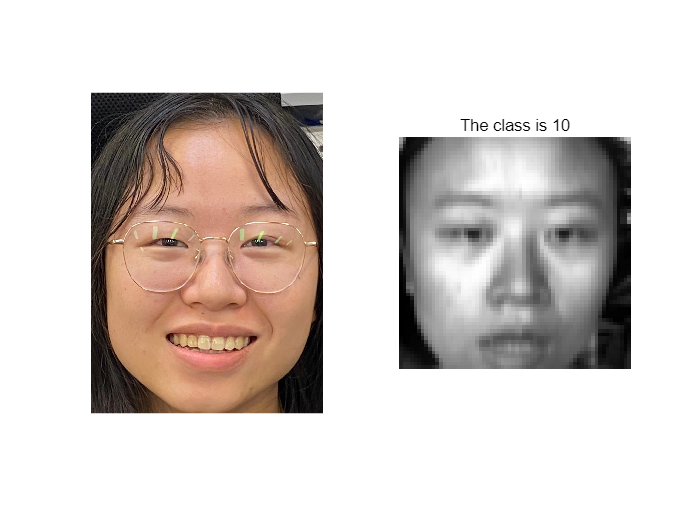

subplot(1,2,1)
imshow(test);
subplot(1,2,2)
imshow(reshape(results.(sprintf('result%d',class))(:,1),[64,64]),[])
title(sprintf('The class is %d',class))

function [mean_face,weights,eigenvectors] = PCA(images,num_images)
% 计算平均人脸
mean_face = mean(images, 2);
% 中心化图像
centered_images = images - repmat(mean_face, 1, num_images);
% 计算协方差矩阵
covariance_matrix = centered_images' * centered_images;
% 计算特征值和特征向量
[eigenvectors, eigenvalues] = eig(covariance_matrix);
% 将特征向量映射回原始空间
eigenfaces = centered_images * eigenvectors;
% 修改选择主成分数量的方法，确保不超过特征向量数量
num_principal_components = min(100, size(eigenfaces, 2));
% 降维
principal_components = eigenfaces(:, end-num_principal_components+1:end);
weights = principal_components' * centered_images;
end 
function [images,num_images] = pre_process(face_images_folder)
image_files = dir(fullfile(face_images_folder, '*.jpg'));
num_images = length(image_files);
image_size = [64, 64];
images = zeros(prod(image_size), num_images);
for i = 1:num_images
image = imread(fullfile(face_images_folder, image_files(i).name));
% gray_image = rgb2gray(image);
resized_image = imresize(image, image_size);
images(:, i) = double(resized_image(:));
end
end